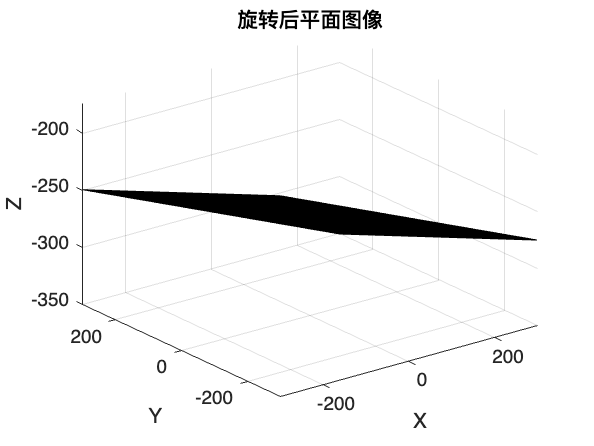

%%%此文件可以得到旋转后平面的一般方程和求坐标方程，以及图像
%%%运行此文件前需要运行计算p的方程
% p = 278.506686890573;
% m = -0.386
% p = 280.3720;
% p = (R - r1 - m)*2
figure

beta = deg2rad(78.169);
alpha = deg2rad(36.795);
theta = beta - pi/2;
z_plat_raw = rr^2/(2*p) - r1 - p/2;
% z_plat_raw = -r1
point = [0 0 z_plat_raw];
n_plat = [cos(beta)*cos(alpha) cos(beta)*sin(alpha) sin(beta)];
u = [cos(beta)*sin(alpha) -cos(beta)*cos(alpha)];
p_rot_plat = rotatePoint(point,u,theta);

% 定义平面方程为函数f(x, y)

view(3)
f = @(x_plat, y_plat) (-n_plat(1)*(x_plat - p_rot_plat(1)) - n_plat(2)*(y_plat - p_rot_plat(2)))/n_plat(3) + p_rot_plat(3);
% 使用fsurf绘制平面
fsurf(f, [-300 300 -300 300])
xlabel('X')
ylabel('Y')
zlabel('Z')
title('旋转后平面图像')

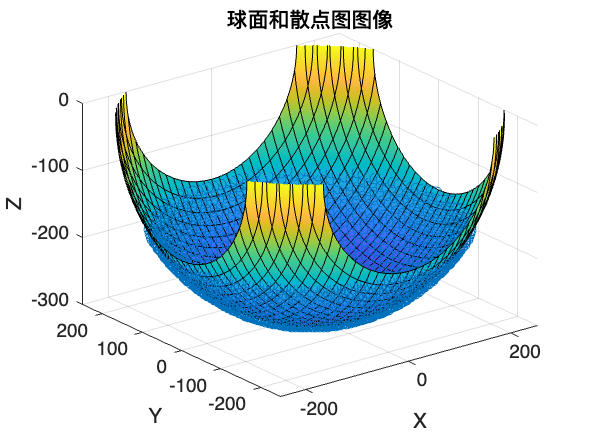

figure
hold on
Point_1 = readmatrix("附件1.csv");
Point_1(:,1) = [];
scatter3(Point_1(:,1),Point_1(:,2),Point_1(:,3))
syms x y;
z = -sqrt(R^2 - x^2 - y^2);

% % 使用 fsurf 绘制图形，并设置网格密度
h = fsurf(z,[-250,250,-250,250]);
% 
% % 获取 ZData 属性
% zData = h.ZData;
% 
% % 将 ZData 中大于 -150 的部分设置为 NaN
% zData(zData > -150) = NaN;
% 
% % 更新 ZData 属性
% h.ZData = zData;

view(3)
grid on
xlabel('X')
ylabel('Y')
zlabel('Z')
title('球面和散点图图像')
hold off

D = -p_rot_plat*n_plat';
disp("旋转后平面参数:")

旋转后平面参数:


ABCD = [n_plat(1) n_plat(2) n_plat(3) -p_rot_plat*n_plat']

ABCD =     0.1642    0.1228    0.9788  256.7475


syms theta_plat phi_plat
rho_plat = p_rot_plat*n_plat'/(n_plat(1)*cos(phi_plat)*cos(theta_plat)+n_plat(2)*cos(phi_plat)*sin(theta_plat)+n_plat(3)*sin(phi_plat));
%绘图测试
% x_test = rho_plat*cos(phi_plat)*cos(theta_plat);
% y_test = rho_plat*cos(phi_plat)*sin(theta_plat);
% z_test = rho_plat*sin(phi_plat);
% fsurf(x_test,y_test,z_test)